## Exploratory Group Assignment

#### Amanda Chang, Dokyun Kim, Jun Park

close all;
clear all;

A) Plot images for 3 different frequencies of sine or cosine waves. Plot the Fourier transforms of the 3 images.

Sine Wave (Frequency: 25.00 Hz)

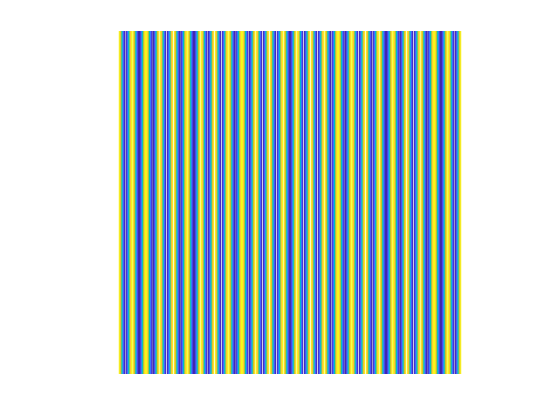

FFT of Sine Wave (Frequency: 25.00 Hz)

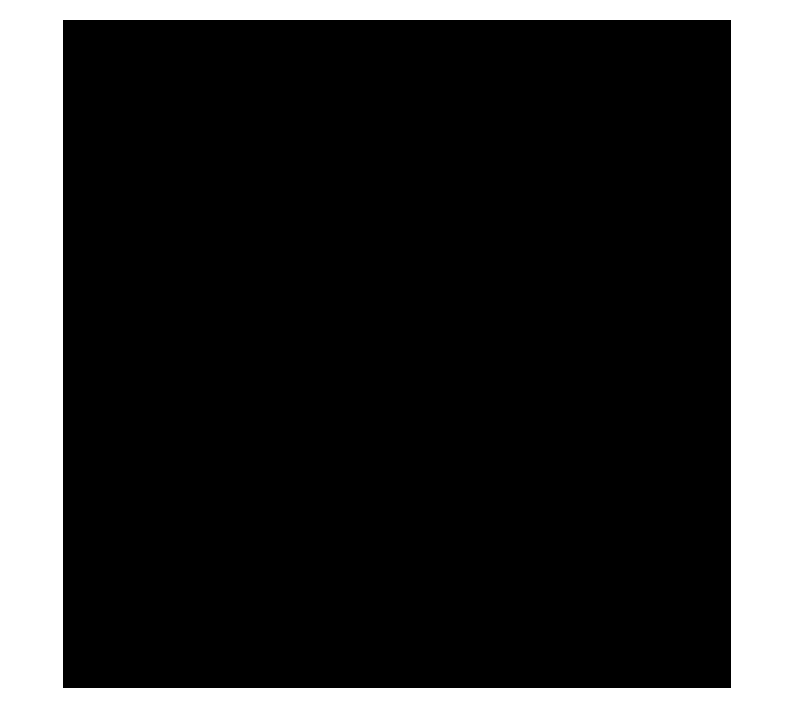

freq1 = 25;
freq2 = 75;
freq3 = 125;
sine_grate(freq1);

Sine Wave (Frequency: 75.00 Hz)

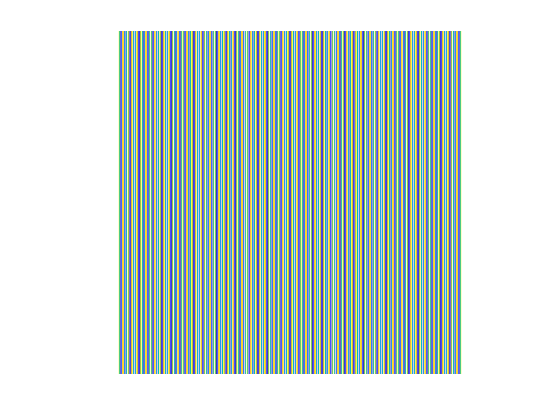

FFT of Sine Wave (Frequency: 75.00 Hz)

sine_grate(freq2);

Sine Wave (Frequency: 125.00 Hz)

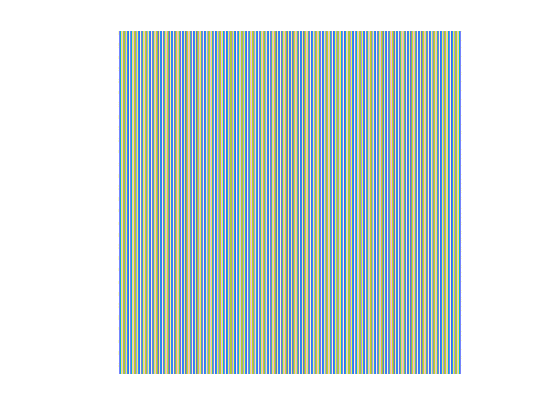

FFT of Sine Wave (Frequency: 125.00 Hz)

sine_grate(freq3);

B) Create these three shapes in MATLAB or Python, find their Fourier transforms, and verify whether the Fourier transforms shown on the right are correct.

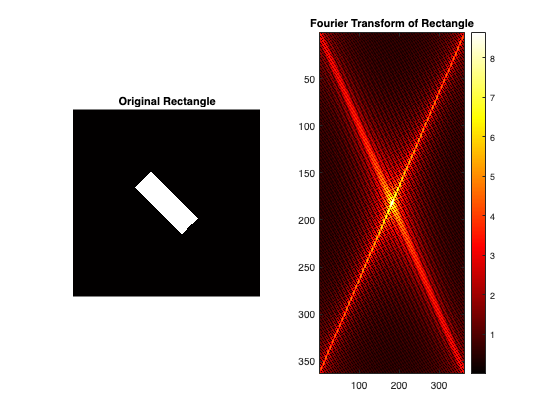

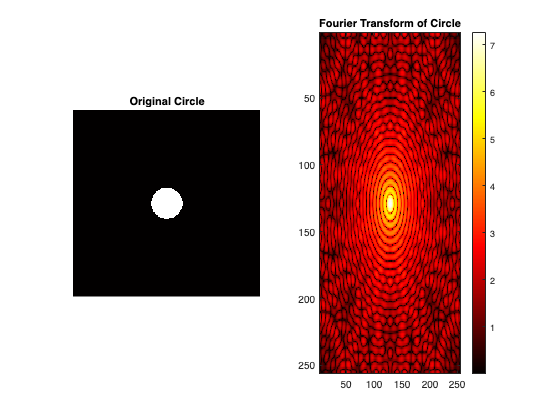

gridSize = 256;
[X, Y] = meshgrid(-gridSize/2:gridSize/2-1, -gridSize/2:gridSize/2-1);

% Rectangle
rect = zeros(gridSize);
rectHeight = round(gridSize / 2);
rectWidth = round(gridSize / 6);
centerY = round(gridSize / 2);
centerX = round(gridSize / 2);
yStart = round(centerY - rectHeight/2);
yEnd = round(centerY + rectHeight/2);
xStart = round(centerX - rectWidth/2);
xEnd = round(centerX + rectWidth/2);
rect(yStart:yEnd, xStart:xEnd) = 1;
rect = imrotate(rect, 45);

% Circle
radius = gridSize / 12;
circle = sqrt(X.^2 + Y.^2) <= radius;

% X Shape
X_shape = zeros(gridSize);
thickness = 3;
diagonalLength = gridSize / 10;
X_shape(abs(X - Y) <= thickness & sqrt(X.^2 + Y.^2) <= diagonalLength) = 1; 
X_shape(abs(X + Y) <= thickness & sqrt(X.^2 + Y.^2) <= diagonalLength) = 1; 

shapes = {rect, circle, X_shape};
shapeNames = {'Rectangle', 'Circle', 'X Shape'};

for k = 1:length(shapes)
    figure;
    shape = shapes{k};
    
    % Compute Fourier Transform
    F = fftshift(fft2(shape));
    
    % Magnitude spectrum (Adding 1 for clearer Visuals)
    magnitudeF = log(1 + abs(F));
    
    subplot(1, 2, 1);
    imshow(shape, []);
    title(['Original ', shapeNames{k}]);

    subplot(1, 2, 2);
    imagesc(magnitudeF);
    title(['Fourier Transform of ', shapeNames{k}]);
    colorbar;
    colormap("hot");
end

C) Use an image of your choice, plot its Fourier transform. Comment on whether interpreting the Fourier Transform was intuitive.

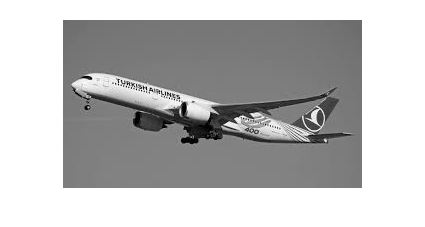

Grayscale Image

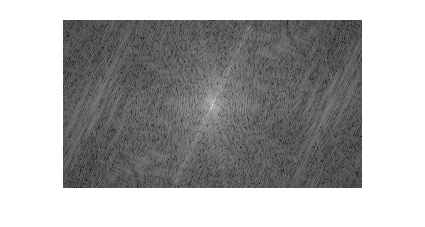

Fourier Transform of plane.jpeg


load 'plane.jpeg'
fourier_image("plane.jpeg")

The Fourier transform of the plane image is intuitive. The primary feature of the fourier transform is a diagonal line with a slope of ~3 cutting through the center of the transform. This line makes sense, as the plane in the image is facing perpendicularly to it, and the contrast between the background and the plane is very linear in the approx. -1/3 slope direction on both the plane's top and bottom. Another notable feature is the plane's wing. For the wing, a faint (mostly up-and-down) line can be observed in the fourier transform also in the perpendicular direction to where the lines that form the visible wing are. Since the background of the image is a fairly uniform color, it also makes sense that the center dot in the fourier transform be bright, as it represents unchanging aspects of the image. Finally, the image has also definitely been compressed, contributing to the mottled appearance in the fourier transform uniformly throughout the frequency range. 

Generally speaking, the fewer clean cut lines there are in an image, the harder an image will be to intuit. Since this is an image of a man-made object in front of a uniform background, it is much easier to interpret than an image of a coral reef, which has few hard lines and very little uniformity.

function fourier_image(image_path)
    % Make image grayscale and plot
    image_matrix = rgb2gray(imread(image_path));
    imshow(image_matrix)
    fprintf("Grayscale Image")

    % Perform FFT and plot
    Y = fft2(image_matrix);
    Y_shifted = log(abs(fftshift(Y)) + 1); % Shift FFT and apply log
    figure();
    imshow(Y_shifted, []);
    fprintf('Fourier Transform of %s\n', image_path)
end